# Problema 2 - Practic

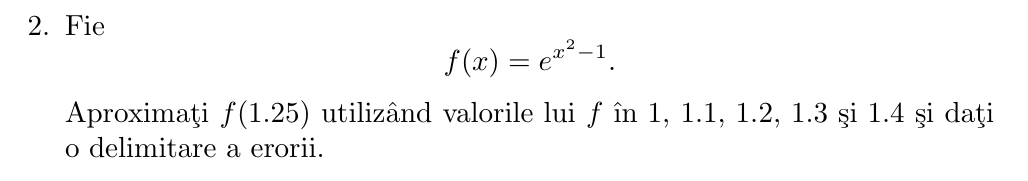

%PB1
function [p_val, p_expr] = lagrangeInterpolation(x_nodes, y_nodes, x_eval)
% INPUT:
%   x_nodes  - vectorul nodurilor de interpolare 
%   y_nodes  - vectorul valorilor functiei in noduri 
%   x_eval   - vectorul punctelor in care se evalueaza polinomul
%
% OUTPUT:
%   p_val    - valorile numerice ale polinomului in punctele x_eval
%   p_expr   - expresia simbolica a polinomului
 
    % Numarul de noduri
    n = length(x_nodes);

    % Asiguram ca x_eval este coloana
    x_eval = x_eval(:);

    % Initializam vectorul rezultat
    p_val = zeros(size(x_eval));

    % Initializare variabila simbolica si polinom simbolic
    syms x;
    p_expr = 0;

    % Construim expresia simbolica si evaluam numeric
    for i = 1:n
        % Initializare L_i(x)
        L_i = 1;
        for j = 1:n
            if j ~= i
                L_i = L_i * (x - x_nodes(j)) / (x_nodes(i) - x_nodes(j));
            end
        end
        % Adunam termenul y_i * L_i(x)
        p_expr = p_expr + y_nodes(i) * L_i;
    end

    % Evaluam numeric in punctele dorite
    for k = 1:length(x_eval)
        p_val(k) = double(subs(p_expr, x, x_eval(k)));
    end

    % Simplificam 
    p_expr = expand(p_expr);  % dezvoltare
end

% Functia f(x) = e^(x^2 - 1)
f = @(x) exp(x.^2 - 1);

% Noduri si valori
x_nodes = 1:0.1:1.4;       % Noduri: 1, 1.1, ..., 1.4
y_nodes = f(x_nodes);      % f in noduri

% Punctul de evaluare
x_eval = 1.25;

% Interpolare Lagrange
[p_val, p_expr] = lagrangeInterpolation(x_nodes, y_nodes, x_eval);

% Aproximare
aprox = p_val(1);
exact = f(x_eval);
eroare = abs(aprox - exact);

% Estimare eroare teoretica
syms x
f_sym = exp(x^2 - 1);
f5 = diff(f_sym, x, 5);                      % a 5-a derivata simbolica
f5_fun = matlabFunction(f5);                % functie anonima
max_f5 = max(abs(f5_fun(linspace(1, 1.4, 100))));  % pe interval

% Calcul produs (noduri)
produs = prod(abs(x_eval - x_nodes));       % |x - x0|*|x - x1|*...

% Delimitare teoretica
limita_eroare = (max_f5 / factorial(5)) * produs;

fprintf('Aproximare f(1.25) = %.10f\n', aprox);

Aproximare f(1.25) = 1.7549573289


fprintf('Valoare exacta     = %.10f\n', exact);

Valoare exacta     = 1.7550546570


fprintf('Eroare absoluta    = %.2e\n', eroare);

Eroare absoluta    = 9.73e-05


fprintf('Delimitare teoretica a erorii <= %.2e\n', limita_eroare);

Delimitare teoretica a erorii <= 2.38e-04
